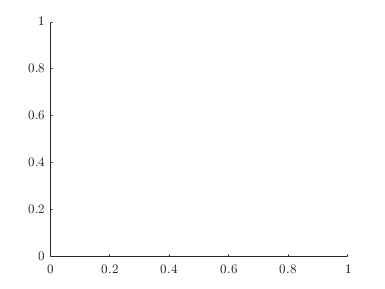

%-------------------------------------------------------------------------%
%------------                    14th April 2022            --------------%
%------------                   Autopilot design            --------------%
%------------            Straight line path following    -----------------%
%-------------------------------------------------------------------------%

close all;clear all; clc;
set(groot,'defaulttextinterpreter','latex');
set(groot,'defaultLegendInterpreter','latex');
% f1 = figure;
% ax1 = axes;
% f2 = figure;
% ax2 = axes;
% f3 = figure;
% ax3 = axes;
% f4 = figure;
% ax4 = axes;
% f5 = figure;
% ax5 = axes;
% f6 = figure;
% ax6 = axes;
% f7 = figure;
% ax7 = axes;
% f8 = figure;
% ax8 = axes;
% f9 = figure;
% ax9 = axes;
% f10 = figure;
% ax10 = axes;
% f11 = figure;
% ax11 = axes;
%--------------- declaration of constant parameters ----------------------%
global  Vgd k_kai k_prop k_Nelson k_kaidot flag1 t_flag1 flag2 t_flag2 figure_type_good
flag1 = true;
flag2 = true;
Vgd = 10;
k_kai = 200;  
k_kaidot = sqrt(k_kai);  % 20 for better curvature profile  %%
figure_type_good = 1;
%-------------------------------------------------------------------------%

%------------------- initial conditions   --------------------------------%

tspan = [0 20];

x0 = 100;
y0 = -100;

k_prop = 0.005;
% flag1 = true(1);
% t_flag1 = zeros(1,2);
% flag2 = true(1);
% t_flag2 = zeros(1,2);

% for i = 1:length(k_prop)

if x0 < 0
   kaid0_prop =  asin(1./(1+ k_prop*(x0).^2)) ;
   kaid_dot0_prop = (2*k_prop*Vgd.*(x0))./((1+k_prop*(x0).^2).^2);
else
   kaid0_prop = pi - asin(1./(1 + k_prop*(x0).^2)) ;  
   kaid_dot0_prop = - (2*k_prop*Vgd.*(x0))./((1 + k_prop*(x0).^2).^2);
end
kai0_prop = kaid0_prop;
kaidot0_prop = kaid_dot0_prop;

kai0_deg = rad2deg(wrapToPi(kai0_prop));


k_Nelson = sqrt(k_prop^2 * x0^2 + 2*k_prop);

kai0_Nelson = pi/2 + atan(k_Nelson.*x0);
kaidot0_Nelson = -(k_Nelson^2*Vgd*x0)./(1+k_Nelson^2.*x0.^2).^(3/2);



%-------------------------------------------------------------------------%

%----------------  vector field construction  ----------------------------%
% range  = -110:10:110;
% [X,Y] = meshgrid(range);
% [kaid,kaid_dot] = vf_proposed(X);
% xdot  = Vgd*cos(kaid);
% ydot  = Vgd*sin(kaid);


%----------------  ode solver   ------------------------------------------%
options = odeset('RelTol',1e-10,'AbsTol',1e-10);

x_initial = [x0;y0;kai0_prop;kaidot0_prop;x0;y0;kai0_Nelson;kaidot0_Nelson];
[t,x] = ode45(@(t,x)fun_stline_upd(t,x,k_prop,k_Nelson) ,tspan, x_initial,options);

k_prop_plot = 0.0002:(0.005-0.0002)/(length(t)-1):0.005;
k_prop_plot = k_prop_plot';
k_prop_indices = 0.0002:(0.005-0.0002)/9:0.005;
for i = 1 :length(t)
    if x0 < 0
        kaid0_prop_plot(i) =  asin(1./(1+ k_prop_plot(i)*(x0).^2)) ;
    else
        kaid0_prop_plot(i) = pi - asin(1./(1 + k_prop_plot(i)*(x0).^2)) ;
    end
    kaid0_prop_plot(i) = rad2deg(wrapToPi(kaid0_prop_plot(i)));
    k_Nelson_plot(i) = sqrt(k_prop_plot(i)^2 * x0^2 + 2*k_prop_plot(i));    
end
kaid0_prop_plot = kaid0_prop_plot' ;
k_Nelson_plot =  k_Nelson_plot';

%----------------------  parameters to plot   ----------------------------%

x_ini = x(1,1) ;
y_ini = x(1,2) ;
x_end = x(end,1) ;
y_end = x(end,2) ;


for j = 1:length(t)
  kai_des_Nelson(j,:) = pi/2 + atan(k_Nelson.*x(j,5));
if x(j,1) < 0
   kai_des_prop(j,:) =  asin(1./(1+ k_prop*(x(j,1)).^2)) ;
   kaidot_des(j,:) = -(2*k_prop*Vgd.*x(j,1))./((1+k_prop*(x(j,1)).^2).^2);
else
   kai_des_prop(j,:) = pi - asin(1./(1 + k_prop*(x(j,1)).^2)) ;  
   kaidot_des(j,:) = - (2*k_prop*Vgd.*x(j,1))./((1 + k_prop*(x(j,1)).^2).^2);
end
end

kaidot_actual_prop = x(:,4);
% kappa_des = kaidot_des./Vgd;
kappa_actual_prop = x(:,4)./Vgd ;
control_effort_prop = trapz(t,(Vgd*x(:,4)).^2);
[val_max_prop, ind_prop] = min(kappa_actual_prop);
x_max_prop = x(ind_prop,1);
 

kaidot_actual_Nelson = x(:,8);
control_effort_Nelson = trapz(t,(Vgd*x(:,8)).^2);
% kappa_des = kaidot_des./Vgd;
kappa_actual_Nelson = x(:,8)./Vgd ;
[val_max_Nelson, ind_Nelson] = min(kappa_actual_Nelson);
x_max_Nelson = x(ind_Nelson,5);

for i = 1:length(t)
 [val_prop(i,:),val_Nelson(i,:)] = fun_kappa(x(i,1),x(i,5));
 ratio_curvature(i,:) = abs(val_prop(i,:))./abs(val_Nelson(i,:)) ;
end
% ratio_curvature = abs(val_max_prop)./abs(val_max_Nelson);



%---------------------- plotting figures ---------------------------------%
% figure_plot = fun_comp_stlineplot(t,x(:,1),x(:,2),x(:,5),x(:,6),...
%     x(:,4),x(:,8),kappa_actual_prop,kappa_actual_Nelson,...
%     x(:,3),x(:,7),x_max_prop,val_max_prop,x_max_Nelson,val_max_Nelson);

% plot parameter
ax_fnt = 23;
lbl_fnt = 25;
ax_wdth = 3;
lgd_fnt = 17;

nframes=50;
Frames=moviein(nframes);

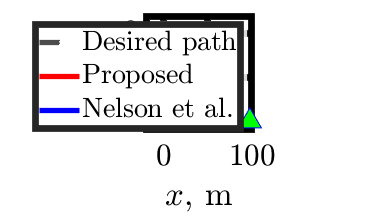

fig1 = figure('Position', [0 0 1920 1080]);
% figure
% subplot(2,2,1)
ax1 = gca;
xl = xline(ax1,0,'--k','linewidth',4);hold(ax1,'on');
ax1.FontSize = ax_fnt;
box on                        % Switch on the box around the axis
ax1.XColor = 'black';         % Box horizontal lines' color
ax1.YColor = 'black';         % Box vertical lines' color
set(ax1,'linewidth',5)        % Axis linewidth (box and grid)
xlabel(ax1,' $ x, $ m','Fontsize',lbl_fnt);
ylabel(ax1,'$ y, $ m','Fontsize',lbl_fnt);

hold(ax1,'on');grid(ax1,'on'); 
axis(ax1,'equal');
ax1.XLim = [-100 100];
ax1.YLim = [-110 100];

h11 = animatedline(ax1,'Color', 'r', 'LineStyle', '-', 'LineWidth', 4) ;
% h12 = animatedline(ax1,'Color', 'r', 'LineStyle', '-', 'LineWidth', 4) ;
h12 = plot(ax1,x(1,1),x(1,2),'^k','MarkerSize',15,'MarkerFaceColor','cyan');
h21 = animatedline(ax1,'Color', 'b', 'LineStyle', '-', 'LineWidth', 4) ;
% h31 = animatedline(ax3,'Color', 'r', 'LineStyle', '-', 'LineWidth', 4) ;
h22 = plot(ax1,x(1,5),x(1,6),'^b','MarkerSize',15,'MarkerFaceColor','green');
l = legend(ax1,[xl h11 h21],'Desired path','Proposed','Nelson et al.');hold on;
% h1 = animatedline('ob','MarkerSize',10,'MarkerFaceColor','blue') ;
% set(gca, 'XLim', [0 1*pi]);
% ax1.XLim = [-100 100];
% ax1.YLim = [-110 100];
% set(gca, 'XLim', [-100 100]);
% set(gca, 'YLim', [-100 100]);

% l = legend(ax1,[h xl h11],'Vector field','Desired path','UAV trajectory');hold on;
% box on
% f = cell(length(x),1) ;
% g = cell(length(x),1) ;
% gg = cell(length(x),1) ;
obj = VideoWriter('Trajectory','MPEG-4');
% obj.Quality = 100;
obj.FrameRate = 50;
% obj1 = VideoWriter('Error','MPEG-4');
% obj1.Quality = 100;
% obj1.FrameRate = 50;
% obj2 = VideoWriter('Course','MPEG-4');
% obj2.Quality = 100;
% obj2.FrameRate = 50;

open(obj);
for i = 1 : 20:length(x)
%     for i = 1:nframes

    set(gca, 'XLim', [-20 100],'YLim', [-110 20]);
    addpoints(h11, x(i,1), x(i,2));hold on;
   
    set(h12,'XData',x(i,1),'YData',x(i,2));
    addpoints(h21, x(i,5), x(i,6));hold on;
     set(h22,'XData',x(i,5),'YData',x(i,6));
%     drawnow
    pause(0.000005)
    f{i} = getframe(gcf) ;
    writeVideo(obj, f{i}) ;
    
end 


% open(obj1);
% open(obj2);
% for i = 1:length(x)
%     writeVideo(obj, f{i}) ;
% %     writeVideo(obj1, gg{i}) ;
% %     writeVideo(obj2, g{i}) ;
% end
obj.close();



% f1;
% % quiver(ax1,X,Y,xdot,ydot,'color',[0.75  0.75   0.75],'linewidth',1);hold on;
% path = xline(ax1,0,'--k','linewidth',2);hold(ax1,'on'); grid(ax1,'on'); 
% plot(ax1,x(:,1),x(:,2),'r','linewidth',2);hold(ax1,'on'); 
% plot(ax1,x(:,5),x(:,6),'b','linewidth',2);hold(ax1,'on'); 
% % plot(x_ini,y_ini,'-o','MarkerSize',10,...
% %     'MarkerEdgeColor','blue',...
% %     'MarkerFaceColor','green'); hold on;
% % plot(x_end,y_end,'-s','MarkerSize',10,...
% %     'MarkerEdgeColor','blue',...
% %     'MarkerFaceColor','cyan'); hold on;
% ax1.FontSize = 13;
% xlabel(ax1,' $ x, $ \ (m)','Fontsize',18);
% ylabel(ax1,'$ y, $ \ (m)','Fontsize',18);
% legend(ax1,'Desired \ path','Proposed','Nelson \ et al. 2007','Fontsize',14);
% axis(ax1, 'equal');
% box(ax1,'on')
% 
% f2;
% h2 = plot(ax2,t,(x(:,1)),'r','LineWidth',2);hold(ax2,'on');grid(ax2,'on');
% % dt_prop = datatip(h2,t_flag1(i),0.2);hold(ax2,'on');grid(ax2,'on');
% h21 = plot(ax2,t,(x(:,5)),'b','LineWidth',2);hold(ax2,'on');grid(ax2,'on');
% % dt_Nelson = datatip(h21,t_flag2(i),0.2);hold(ax2,'on');grid(ax2,'on');
% % yline(ax2,0.2,'k','LineWidth',2);hold(ax2,'on');grid(ax2,'on');
% ax2.FontSize = 13;
% xlabel(ax2,'Time, \ $t$, \ (s)','Fontsize',18);
% ylabel(ax2,'Cross-track \ error, \ $x$, \ (m)','Fontsize',18);
% legend(ax2,'Proposed','Nelson \ et al. 2007','Fontsize',14);
% 
% f3;
% plot(ax3,x(:,1),kaidot_actual_prop,'r','LineWidth',2);hold(ax3,'on');grid(ax3,'on');
% plot(ax3,x(:,5),kaidot_actual_Nelson,'b','LineWidth',2);
% ax3.FontSize = 13;
% xlabel(ax3,'Cross-track \ error, \ $x$, \ (m)','Fontsize',18);
% ylabel(ax3,'Course \ rate,  \ $\dot{\chi}$, \ ( rad./s) ','Fontsize',18);
% legend(ax3,'Proposed','Nelson \ et al. 2007','Fontsize',14);
% 
% 
% f4;
% h4 = plot(ax4,x(:,1),kappa_actual_prop,'r','LineWidth',2);hold(ax4,'on');grid(ax4,'on');
% h41 = plot(ax4,x(:,5),kappa_actual_Nelson,'b','LineWidth',2);
% h42 = plot(ax4,x_max_prop,val_max_prop,'-s','MarkerSize',10,...
%     'MarkerEdgeColor','black',...
%     'MarkerFaceColor','cyan'); hold(ax4,'on');grid(ax4,'on');
% h42.Annotation.LegendInformation.IconDisplayStyle = 'off';
% h43 = plot(ax4,x_max_Nelson,val_max_Nelson,'-s','MarkerSize',10,...
%     'MarkerEdgeColor','black',...
%     'MarkerFaceColor','green'); hold(ax4,'on');grid(ax4,'on');
% h43.Annotation.LegendInformation.IconDisplayStyle = 'off';
% % plot(ax4,[x_max_prop x_max_prop],[0 val_max_prop],'--','color',[0.75 0.75 0.75],'linewidth',2);hold(ax4,'on');grid(ax4,'on');
% % plot(ax4,[x_max_Nelson x_max_Nelson],[0 val_max_Nelson],'--','color',[0.75 0.75 0.75],'linewidth',2);hold(ax4,'on');grid(ax4,'on');
% % plot(ax4,[0 x_max_prop],[val_max_prop val_max_prop],'--','color',[0.75 0.75 0.75],'linewidth',2);hold(ax4,'on');grid(ax4,'on');
% % plot(ax4,[0 x_max_Nelson],[val_max_Nelson val_max_Nelson],'--','color',[0.75 0.75 0.75],'linewidth',2);hold(ax4,'on');grid(ax4,'on');
% dt_prop = datatip(h4,x_max_prop,val_max_prop);hold(ax4,'on');grid(ax4,'on');
% h4.DataTipTemplate.DataTipRows(1).Format = '%.2f';
% h4.DataTipTemplate.DataTipRows(2).Format = '%.3f';
% dt_Nelson = datatip(h41,x_max_Nelson,val_max_Nelson);hold(ax4,'on');grid(ax4,'on');
% h41.DataTipTemplate.DataTipRows(1).Format = '%.2f';
% h41.DataTipTemplate.DataTipRows(2).Format = '%.3f';
% ax4.FontSize = 13;
% xlabel(ax4,'Cross-track \ error, \ $x$, \ (m)','Fontsize',18);
% ylabel(ax4,'Curvature, \ $\kappa$, \ (m $ ^-1 $) ','Fontsize',18);
% legend(ax4,'Proposed','Nelson \ et al. 2007','$\kappa_{m} $ Proposed','$\kappa_{m} $ Nelson \ et al. 2007','','','Fontsize',14);
% 
% f5;
% plot(ax5,t,kaidot_actual_prop*(180/pi),'r','LineWidth',2);hold(ax5,'on');grid(ax5,'on');
% plot(ax5,t,kaidot_actual_Nelson*(180/pi),'b','LineWidth',2);
% ax5.FontSize = 13;
% xlabel(ax5,'Time, \ $t$, \ (s)','Fontsize',18);
% ylabel(ax5,'Course \ rate,  \ $\dot{\chi}$, \ ( deg.) ','Fontsize',18);
% legend(ax5,'Proposed','Nelson \ et al. 2007','Fontsize',14);
% 
% f6;
% plot(ax6,t,kappa_actual_prop,'r','LineWidth',2);hold(ax6,'on');grid(ax6,'on');
% plot(ax6,t,kappa_actual_Nelson,'b','LineWidth',2);
% ax6.FontSize = 13;
% xlabel(ax6,'Time, \ $t$, \ (s)','Fontsize',18);
% ylabel(ax6,'Curvature, \ $\kappa$, \ (m $ ^-1 $) ','Fontsize',18);
% legend(ax6,'Proposed','Nelson \ et al. 2007','Fontsize',14);
% 
% f7;
% plot(ax7,t,x(:,3)*(180/pi),'r','linewidth',2);hold(ax7,'on');grid(ax7,'on');
% plot(ax7,t,x(:,7)*(180/pi),'b','linewidth',2);
% ax7.FontSize = 13;
% xlabel(ax7,'Time, \ $ t, $ \ (s)','Fontsize',18);
% ylabel(ax7,'Course \ angle, \ $ \chi$, \ ( deg.)','Fontsize',18);
% legend(ax7,'Proposed','Nelson \ et al. 2007','Fontsize',14);
% 
% 
% f8;
% plot(ax8,x(:,1),x(:,3)*(180/pi),'r','linewidth',2);hold(ax8,'on');grid(ax8,'on');
% plot(ax8,x(:,5),x(:,7)*(180/pi),'b','linewidth',2);
% ax8.FontSize = 13;
% xlabel(ax8,'Cross-track \ error, \ $x$, \ (m)','Fontsize',18);
% ylabel(ax8,'Course \ angle, \ $ \chi$,\ ( deg.)','Fontsize',18);
% legend(ax8,'Proposed','Nelson \ et al. 2007','Fontsize',14);
% 
% 
% 
% f9;
% plot(ax9,x(:,1),kai_des_prop.*(180/pi),'r','linewidth',2);hold(ax9,'on');grid(ax9,'on');
% plot(ax9,x(:,1),x(:,3)*(180/pi),'b','linewidth',2);
% ax9.FontSize = 13;
% xlabel(ax9,'Cross-track \ error, \ $x$, \ (m)','Fontsize',18);
% ylabel(ax9,'Course \ angle, \ $ \chi$,\ ( deg.)','Fontsize',18);
% legend(ax9,'Desired','Actual ','Fontsize',14);
% 
% 
% f10;
% plot(ax10,x(:,5),kai_des_Nelson.*(180/pi),'r','linewidth',2);hold(ax10,'on');grid(ax10,'on');
% plot(ax10,x(:,5),x(:,7)*(180/pi),'b','linewidth',2);
% ax10.FontSize = 13;
% xlabel(ax10,'Cross-track \ error, \ $x$, \ (m)','Fontsize',18);
% ylabel(ax10,'Course \ angle, \ $ \chi$,\ ( deg.)','Fontsize',18);
% legend(ax10,'Desired Nelson','Actual Nelson','Fontsize',14);
% 
% f11;
% yyaxis left
% plot(ax11,k_prop_plot,kaid0_prop_plot,'s-','MarkerFaceColor','red','MarkerEdgeColor','black','MarkerIndices', 1:552:length(k_prop_plot),'linewidth',2);hold(ax11,'on');grid(ax11,'on');
% % plot(ax14,k_prop,kai0_deg,'s-','MarkerFaceColor','red','MarkerEdgeColor','black','MarkerIndices', 1:length(k_prop),'linewidth',2);hold(ax14,'on');grid(ax14,'on');
% ax11.FontSize = 13;
% ylabel(ax11,'Course \ angle, \ $ \chi$,\ ( deg.)','Fontsize',18');hold(ax11,'on');grid(ax11,'on');
% axis(ax11,[0 k_prop(end) 90 180])
% yyaxis right
% plot(ax11,k_prop_plot,k_Nelson_plot,'o-','MarkerFaceColor','green','MarkerEdgeColor','black', 'MarkerIndices', 1:552:length(k_prop_plot),'linewidth',2);
% axis(ax11,[0 k_prop(end) 0 1])
% ylabel(ax11,' Nelson et al. \ gain, \ $ k$ ','Fontsize',18');hold(ax11,'on');grid(ax11,'on');
% xlabel(ax11,' Proposed \ gain, \ $k_{s}$ ','Fontsize',18);




function out = fun_stline_upd(t,x,k_prop,k_Nelson)
global Vgd k_kai k_kaidot flag1 t_flag1 flag2 t_flag2 

if (flag1 == true) && (x(1)<0.2)
    t_flag1 = t;
    flag1 = false;
end

if (flag2 == true) && (x(5)<0.2)
    t_flag2 = t;
    flag2 = false;
end

% 
% if (flag2 == true) && (x(5)<0.2)
%     t_flag2 = t;
%     flag2 = false;
% end

if x(1) < 0
   kaid_prop =  asin(1./(1+ k_prop*(x(1)).^2)) ;
   kaid_dot_prop = 2*k_prop*Vgd.*(x(1))./((1+k_prop*(x(1)).^2).^2);
else
   kaid_prop = pi - asin(1./(1 + k_prop*(x(1)).^2)) ;  
   kaid_dot_prop = - 2*k_prop*Vgd.*(x(1))./((1 + k_prop*(x(1)).^2).^2);
end

kaid_Nelson = pi/2 + atan(k_Nelson.*x(5));
kaid_dot_Nelson = -(k_Nelson^2*Vgd*x(5))./(1+k_Nelson^2.*x(5).^2).^(3/2);
% Vad = sqrt(Vgd^2  + wx^2 +wy^2 - 2*(Vgd*wx*cos(kaid) + Vgd*wy*sin(kaid)));
% 
% psid = kaid + asin((wx*sin(kaid)-wy*cos(kaid))/Vad);
% psi = x(3) + asin((wx*sin(x(3))-wy*cos(x(3)))/x(5));
% 
% Vg = sqrt(x(5)^2  + wx^2 +wy^2 + 2*x(5)*(wx*cos(psi) + wy*sin(psi)));


out(1,1) = Vgd*cos(x(3));
out(2,1) = Vgd*sin(x(3));
out(3,1) = x(4) ;
out(4,1) = k_kai*(kaid_prop - x(3)) + k_kaidot*(kaid_dot_prop - x(4) )  ;

out(5,1) = Vgd*cos(x(7));
out(6,1) = Vgd*sin(x(7));
out(7,1) = x(8) ;
out(8,1) = k_kai*(kaid_Nelson - x(7)) + k_kaidot*(kaid_dot_Nelson - x(8))  ;
end

function [val_prop,val_Nelson]  = fun_kappa(x_prop,x_Nelson)
global Vgd k_prop k_Nelson
% for i = 1:length(x_prop)
    if x_prop < 0
        kaidot_des = -(2*k_prop*Vgd.*x_prop)./((1+k_prop*(x_prop).^2).^2);
        kappa_des_prop = kaidot_des./Vgd ;
    else      
        kaidot_des = - (2*k_prop*Vgd.*x_prop)./((1 + k_prop*(x_prop).^2).^2);
        kappa_des_prop = kaidot_des./Vgd ;
    end
[val_prop, ind_prop] = max(abs(kappa_des_prop));
% x_max_prop = x(ind_prop,1);
kaid_dot_Nelson = -(k_Nelson^2*Vgd*x_Nelson)./(1+k_Nelson^2.*x_Nelson.^2).^(3/2);
kappa_des_Nelson = kaid_dot_Nelson./Vgd ;
[val_Nelson, ind_Nelson] = max(abs(kappa_des_Nelson));
% x_max_Nelson = x(ind_Nelson,1);
% ratio_curvature(i,1) = abs(val_max_prop(i,1))./abs(val_max_Nelson(i,1)) ;
%end
end

function [kaid,kaid_dot] = vf_proposed(x)
global Vgd  k_prop 
for i = 1:length(x)
    for j = 1:length(x)
if x(i,j) < 0
   kaid(i,j) = asin(1./(1+k_prop*(x(i,j)).^2)) ;
   kaid_dot(i,j) =  2*k_prop*Vgd.*(x(i,j))./((1+k_prop*(x(i,j)).^2).^2);
else
   kaid(i,j) = pi - asin(1./(1+k_prop*(x(i,j)).^2)) ;
   kaid_dot(i,j) = - 2*k_prop*Vgd.*(x(i,j))./((1+k_prop*(x(i,j)).^2).^2);
end
    end
end
end

